Int1 = importdata("Int1.txt");
x = Int1(:,1);
v = Int1(:,2);


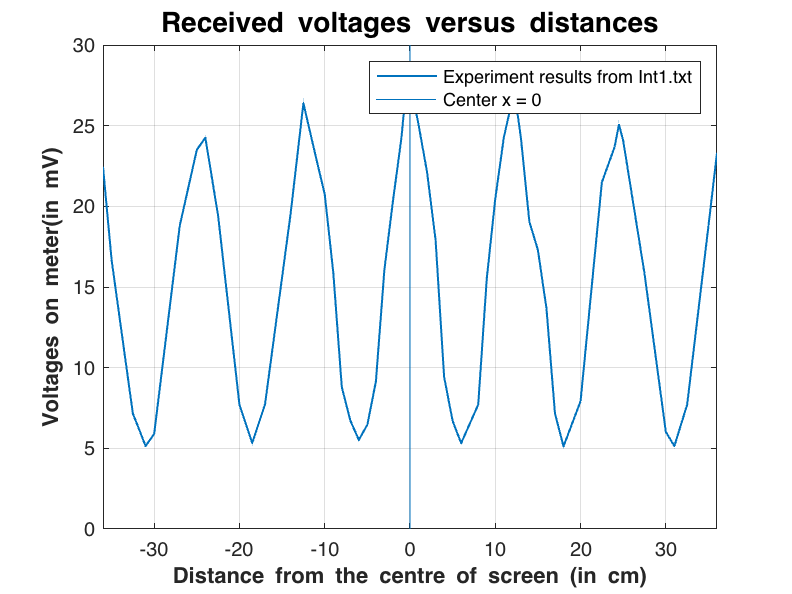

plot(x,v,LineWidth=1);
line([0 0],[0 30])
grid on;
xlabel('{\bfDistance from the centre of screen (in cm)}');
ylabel('{\bfVoltages on meter(in mV)}');
axis([-36 36 0 30]);
legend("Experiment results from Int1.txt", "Center x = 0");
title('{\bfReceived voltages versus distances}','FontSize',14)

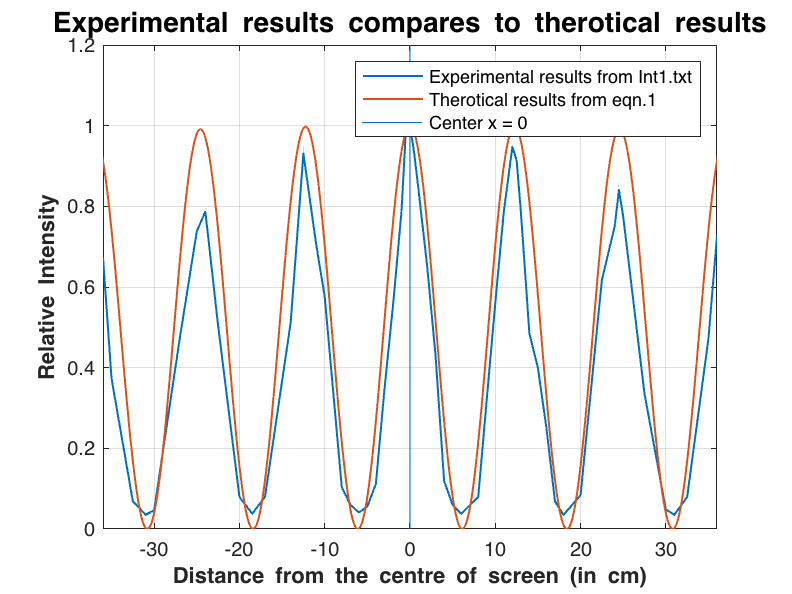

plot(x,(v/max(v)).^2,LineWidth=1);
grid on;
xlabel('{\bfDistance from the centre of screen (in cm)}')
ylabel('{\bfRelative Intensity}')
hold on;
%
d=0.63;             % separation between the sources (in m)
D=2.55;             % distance from sources to screen (in m)
lambda=0.03;        % wavelength (in m)
k=2*pi/lambda;
%
x=-0.5:0.001:0.5;   % to cover 50 cm at either side of the centre
theta1=atan((d/2-x)/D);
theta2=atan((d/2+x)/D);
l1=D./cos(theta1);
l2=D./cos(theta2);
j=0+1i;
Et=exp(-j*k*l1)./l1+exp(-j*k*l2)./l2;
Et=Et.*conj(Et)/(max(Et)^2);
%
axis([-36 36 0 1.2]);
y=x*100;            % converting to cm
plot(y,abs(Et), LineWidth=1);
line([0 0],[0 1.2])
legend("Experimental results from Int1.txt", ...
    "Therotical results from eqn.1","Center x = 0")
title('{\bfExperimental results compares to therotical results}','FontSize',14)
hold off;